# FFT Example Code

Last Date Modified: 2/1/2022

Authors: Spring 2022 Teaching Team

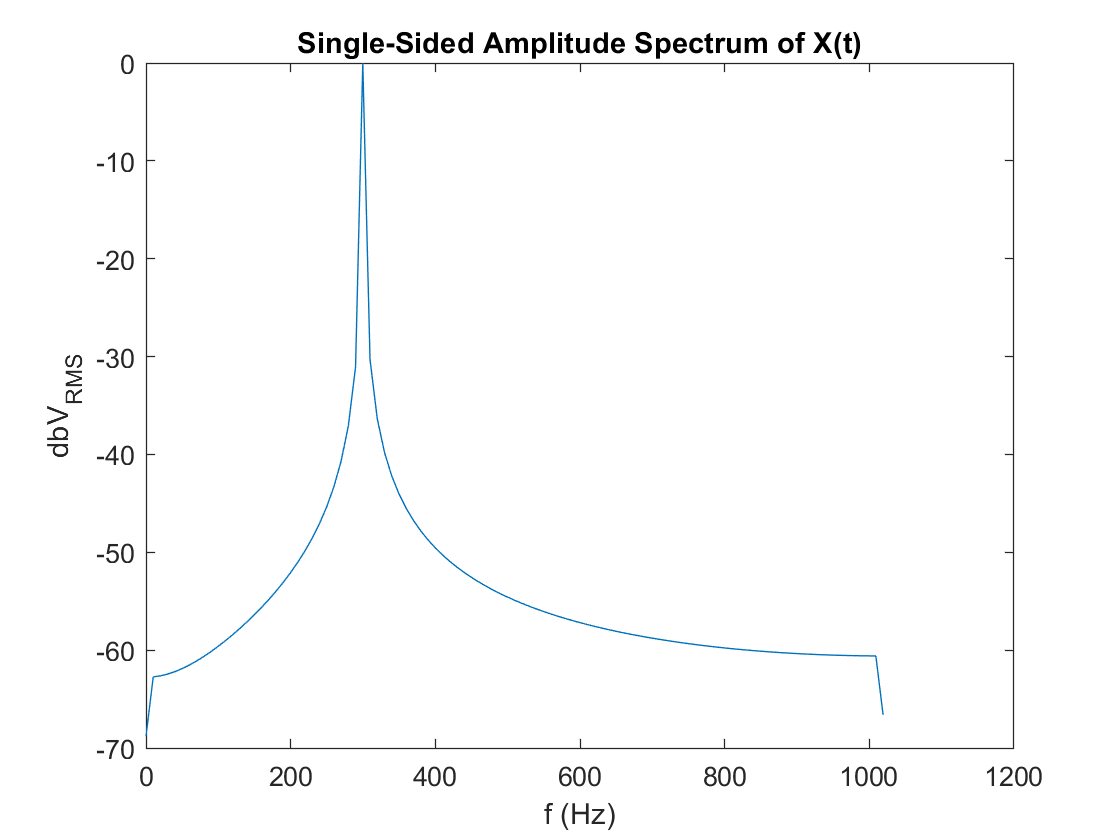

%Set your sampling frequency (must be much higher than f of signal)
Fs = 2048;       

% create a time vector from 0 to t_end, spaced by dt = 1/Fs (dt = 
% ~0.5 milliseconds)
t = 0:1/Fs:0.1;

% create the signal: a cosine, amplitude = 1 V, at 300 Hz
x =  sin(2*pi*300*t);
%Create your length veriable L defined as the length of vector x
L = length(x);

%Take the fft of your signal
Y = fft(x);

% Compute the two-sided voltage spectrum V2 in the real plane. We use abs()
% to get magnitude of the complex number.
V2 = abs(Y/L);

%We want to view the single sided ampolitude spectrum, so throw away all
%negative frequency components.
V1 = V2(1:floor(L/2+1));

%The negative components carry ampllitude, we multiply the positive
%components (V1) by 2 to include the amplitude of the components that were
%thrown away. They are symmetric about f = 0. We do not double the DC
%component hence the (2:end-1)
V1(2:end-1) = 2*V1(2:end-1);

% Define your frequency vector f in the fourier domain. The amount of
% points and span of them in the frequency dokmain are decided by the number of points captured in
% the time domain, and scaling completed by the fft function. Their span is
% adjusted by ~1/2 since we threw away negative components and now span
% less of thefrequency space.
f = Fs*(0:(L/2))/L;

% We like to plot in dB_VRMS, so convert your fft from linear amplitude to
% voltage dB_VRMS
V_RMS1(2:end) = V1(2:end)/sqrt(2)
dB1 = 20*log10(V_RMS1);

%Now, plot your results
plot(f,dB1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('dbV_{RMS}')